% Clear Workspace
clear all;
close all;

% Run Simultion for Noise Calibration
set_param('Filter_Bank_Model/Gain1','Gain','0.35');
sim('Filter_Bank_Model',100);

% Total Noise Power
noise_total = load('noise.mat');
noise_data_total = noise_total.ans.Data; % Time-series data for noise
noise_data_total = reshape(noise_data_total,[length(noise_data_total), 1]);

% Total Noise Power
noise_bw = load('noise_bw.mat');
noise_data_bw = noise_bw.ans.Data; % Time-series data for noise
noise_data_bw = reshape(noise_data_bw,[length(noise_data_bw), 1]);

% Signal Power
signal = load('sig.mat');
signal_data = signal.ans.Data; % Time-series data for signal
signal_data = reshape(signal_data,[length(signal_data), 1]);

% Noise power in one Filter
noise_bw_total = load('sig_noise_bw.mat');
sig_noise_bw_data = noise_bw_total.ans.Data; % Time-series data for signal
sig_noise_bw_data = reshape(sig_noise_bw_data,[length(sig_noise_bw_data), 1]);


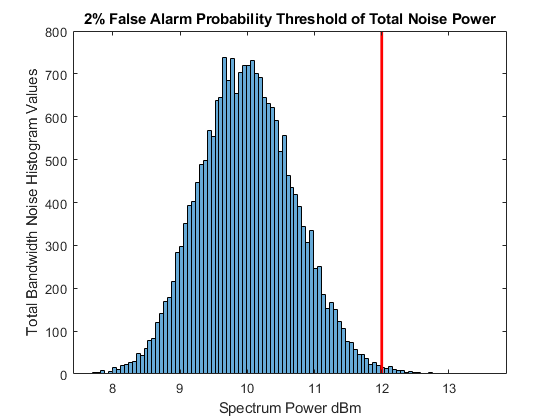

% Plot histogram of noise data to determine detection thresholding,
% magnitude of bina are arbitrary 
% Typical probability of detection might be set as 10% for false positives
histogram(noise_data_total,100)
xlabel('Spectrum Power dBm');
ylabel('Total Bandwidth Noise Histogram Values');
title('2% False Alarm Probability Threshold of Total Noise Power');
line([12, 12], ylim, 'LineWidth', 2, 'Color', 'r');

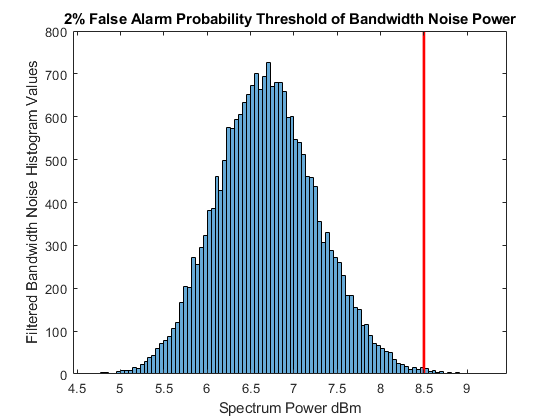

histogram(noise_data_bw,100)
xlabel('Spectrum Power dBm');
ylabel('Filtered Bandwidth Noise Histogram Values');
title('2% False Alarm Probability Threshold of Bandwidth Noise Power');
line([8.5, 8.5], ylim, 'LineWidth', 2, 'Color', 'r');

%histogram(signal_data,100)
% Determine SNR
avg_sig = mean(signal_data);
avg_noise_total = mean(noise_data_total);
avg_noise_bw = 6.7; %mean(noise_bw_data);
snr_total = 10*log10(avg_sig)-10*log10(avg_noise_total);
snr_bw = 10*log10(avg_sig)-10*log10(avg_noise_bw)

snr_bw = -0.3897

% Set a threshold for total bandwidth of 12
Pd_tot = sum(noise_data_total > 12)/length(noise_data_total)*100

Pd_tot = 0.4036

% Set a threshold for bandpass bandwidth of 28
Pd_bw = sum(noise_data_bw > 8.5)/length(noise_data_bw)*100

Pd_bw = 0.2177